 Section-1 

%By Kunal Kishore ,16093
% m = inital number of steps ,i.e degree of precision
% from where calculation should start
m=4;

% k ,largest value of steps,i.e  degree of precision =
% till which to calculate
k=1024;

%[a,b] is the interval over which function to be intregated
a=0;
b=1;
n=m;
i = 1 ;
N = ones(10,1);

while (n <= k)
    N(i) =n;
    
    n = n*2;
    i = i+1;
end

format longE
%function to be intregated
syms f(x)
f(x) =  x^3 + sin(x);

I_real = double(int(f(x),[a,b]))

I_real =      7.096976941318602e-01

 Trapeziodal Rule Calculation

%For calculating Trapeziodal Rule
n=m;
i = 1 ;
area_by_T = ones(10,1);
while (n <= k)
    h=(b-a)/n ;
    x=a:h:b ;
    y = f(x) ;
    area_by_T(i) = trapz(x,y);
    n = n*2;
    i = i+1;
end

errorT =area_by_T -ones(10,1)*I_real ;
disp("Trapeziodal Rule")

Trapeziodal Rule


table(N , area_by_T , errorT)

ans = 10×3 table
             N                   area_by_T                 errorT       
    ____________________    ____________________    ____________________
    4.00000000000000e+00    7.22925937571502e-01    1.32282434396419e-02
    8.00000000000000e+00    7.13005223491722e-01    3.30752935986134e-03
    1.60000000000000e+01    7.10524605712215e-01    8.26911580354528e-04
    3.20000000000000e+01    7.09904423853836e-01    2.06729721975552e-04
    6.40000000000000e+01    7.09749376676525e-01    5.16825446643665e-05
    1.28000000000000e+02    7.09710614775162e-01    1.29206433016060e-05
    2.56000000000000e+02    7.09700924293132e-01    3.23016127146136e-06
    5.12000000000000e+02    7.09698501672206e-01    8.07540345815205e-07
    1.02400000000000e+03    7.09697896016948e-01    2.01885088202403e-07
    1.00000000000000e+00    1.00000000000000e+00    2.90302305868140e-01

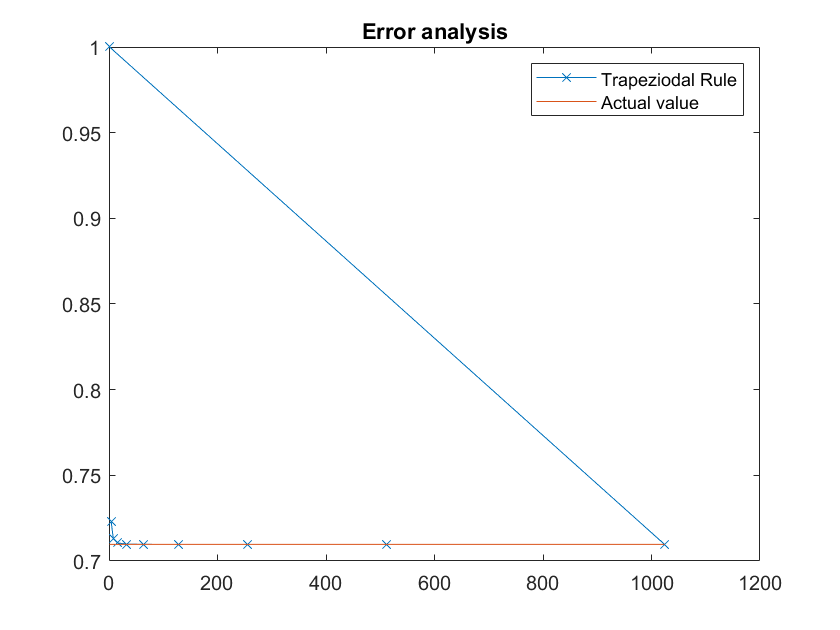


plot(N , area_by_T,'-x')
hold on
plot(N ,I_real*ones(10,1))
hold off
title("Error analysis")
legend("Trapeziodal Rule","Actual value")

Simpson Rule Calculation

%For calculating Simpson 1/3 Rule 
n = m ;
i = 1 ;
area_by_S= ones(10,1) ;
while (n <= k)
    
    h = (b-a)/n;
    curr = f(a) + f(b);
    for q = 1:2:n-1   %n is even
        curr = curr + 4*f(a + q*h);
        
    end
    for q = 2:2:n-2 
        curr = curr +2*f(a + q*h);
    end
    
    area_by_S(i) = 1/3 *h *curr;
    i=i+1;
    n = n*2;
    
end

disp("Simpson 1/3 Rule ")

Simpson 1/3 Rule 



errorS = area_by_S -ones(10,1)*I_real;
table(N , area_by_S , errorS)

ans = 10×3 table
             N                   area_by_S                 errorS       
    ____________________    ____________________    ____________________
    4.00000000000000e+00    7.09707744927311e-01    1.00507954506890e-05
    8.00000000000000e+00    7.09698318798461e-01    6.24666601223289e-07
    1.60000000000000e+01    7.09697733119046e-01    3.89871855910329e-08
    3.20000000000000e+01    7.09697696567710e-01    2.43584930004204e-09
    6.40000000000000e+01    7.09697694284088e-01    1.52227341843059e-10
    1.28000000000000e+02    7.09697694141374e-01    9.51405620952528e-12
    2.56000000000000e+02    7.09697694132455e-01    5.94635451989234e-13
    5.12000000000000e+02    7.09697694131897e-01    3.71924713249427e-14
    1.02400000000000e+03    7.09697694131863e-01    2.33146835171283e-15
    1.00000000000000e+00    1.00000000000000e+00    2.90302305868140e-01

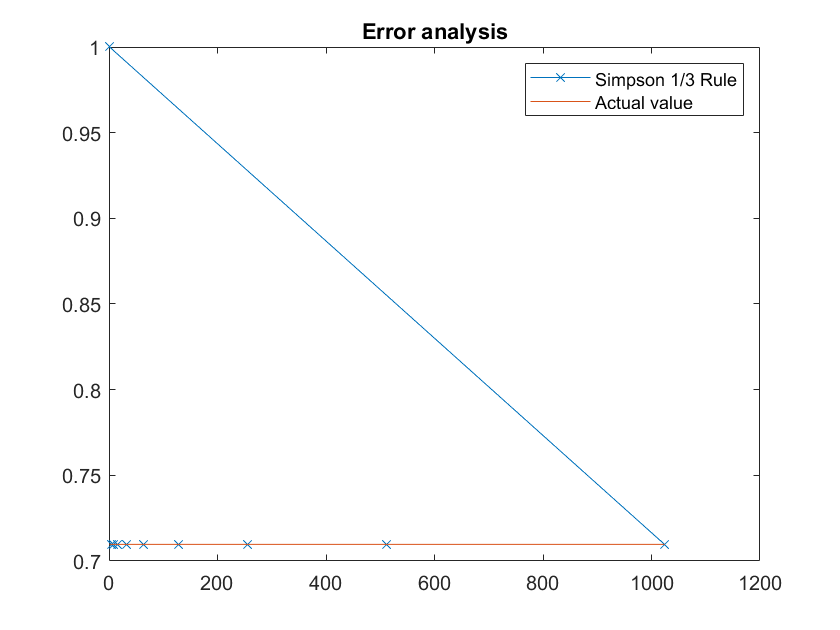


plot(N , area_by_S,'-x')
hold on
plot(N ,I_real*ones(10,1))
hold off
title("Error analysis")
legend("Simpson 1/3 Rule","Actual value")

Gaussian quadrature calculation

%For calculating Gauss–Legendre quadrature

n = m ;
i = 1 ;
area_by_G = ones(10,1);

while (n <= k )
    h=(b-a)/n;
    
    [xi,wi] = lgwt(n,a,b) ; 
    curr = 0;
    z = 1;
    while  (z <= n) 
        curr = curr + wi(z)*f(xi(z));
        z=z+1;    
    end
    area_by_G(i) = curr;
    
    i = i+1;
    n = n*2 ;
 
end

disp("Gauss–Legendre quadrature ")

Gauss–Legendre quadrature 



errorG =area_by_G -ones(10,1)*I_real ;
table(N , area_by_G,abs(errorG))

ans = 10×3 table
             N                   area_by_G                  Var3        
    ____________________    ____________________    ____________________
    4.00000000000000e+00    7.09697693863893e-01    2.67967203981812e-10
    8.00000000000000e+00    7.09697694131861e-01    6.66133814775094e-16
    1.60000000000000e+01    7.09697694131860e-01    1.11022302462516e-16
    3.20000000000000e+01    7.09697694131860e-01    2.22044604925031e-16
    6.40000000000000e+01    7.09697694131860e-01    6.66133814775094e-16
    1.28000000000000e+02    7.09697694131860e-01    3.33066907387547e-16
    2.56000000000000e+02    7.09697694131860e-01    5.55111512312578e-16
    5.12000000000000e+02    7.09697694131860e-01    0.00000000000000e+00
    1.02400000000000e+03    7.09697694131861e-01    8.88178419700125e-16
    1.00000000000000e+00    1.00000000000000e+00    2.90302305868140e-01

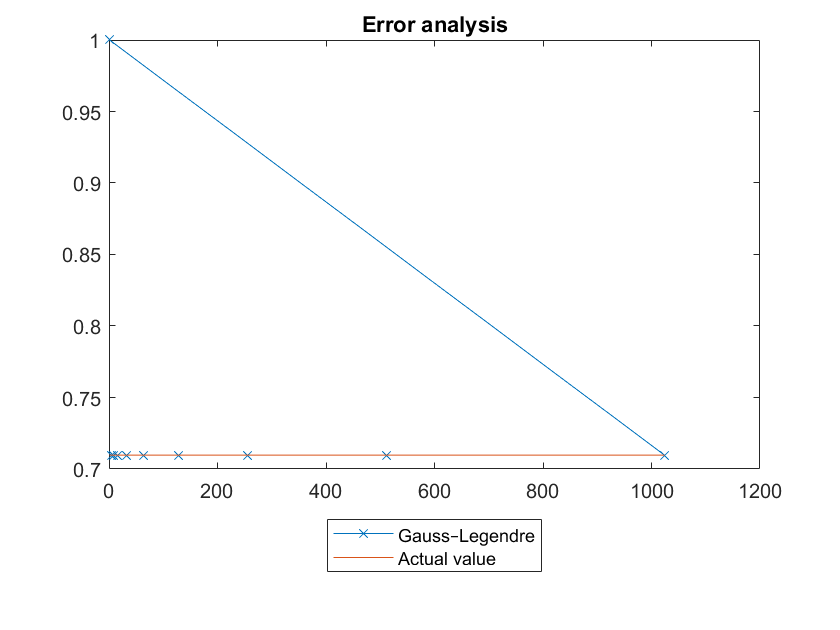


plot(N , area_by_G,'-x')
hold on
plot(N ,I_real*ones(10,1))
hold off
title("Error analysis")
x=legend("Gauss–Legendre","Actual value");
x.Location ='southoutside'	;

Displaying the result

fprintf("Actual value of integration:%i",I_real)

Actual value of integration:7.096977e-01

disp(table(N,area_by_T , area_by_S , area_by_G))

             N                   area_by_T               area_by_S               area_by_G      
    ____________________    ____________________    ____________________    ____________________
    4.00000000000000e+00    7.22925937571502e-01    7.09707744927311e-01    7.09697693863893e-01
    8.00000000000000e+00    7.13005223491722e-01    7.09698318798461e-01    7.09697694131861e-01
    1.60000000000000e+01    7.10524605712215e-01    7.09697733119046e-01    7.09697694131860e-01
    3.20000000000000e+01    7.09904423853836e-01    7.09697696567710e-01    7.09697694131860e-01
    6.40000000000000e+01    7.09749376676525e-01    7.09697694284088e-01    7.09697694131860e-01
    1.28000000000000e+02    7.09710614775162e-01    7.09697694141374e-01    7.09697694131860e-01
    2.56000000000000e+02    7.09700924293132e-01    7.09697694132455e-01    7.0969769413

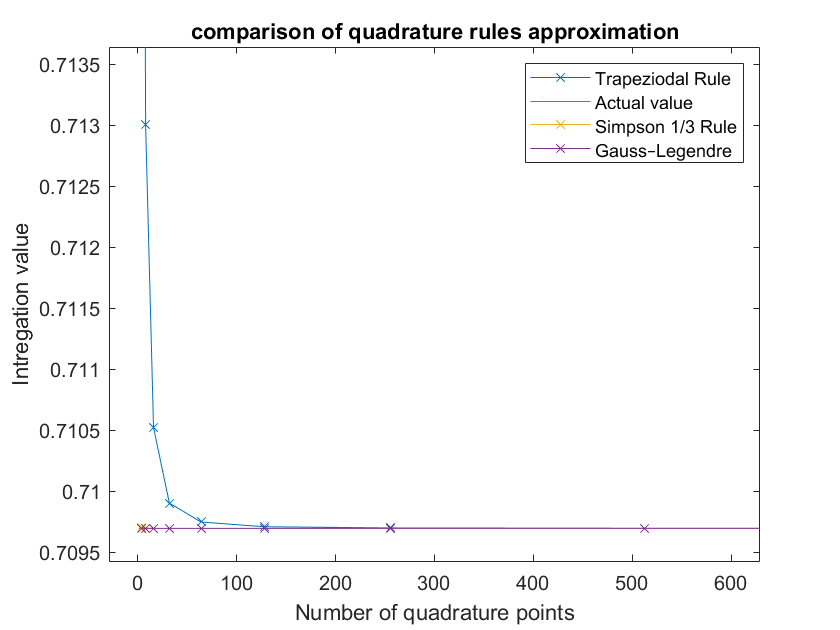


plot(N,area_by_T,'-x')
xlabel("Number of quadrature points")
ylabel("Intregation value")
hold on
plot(N ,I_real*ones(10,1))
plot(N,area_by_S,'-x')
plot(N,area_by_G,'-x')
hold off
title("comparison of quadrature rules approximation")
legend("Trapeziodal Rule ","Actual value","Simpson 1/3 Rule " ...
   ,"Gauss–Legendre ")
xlim([-29 629])
ylim([0.70943 0.71364])

disp("Error comparison")

Error comparison


disp(table(N,errorT , errorS , errorG))

             N                     errorT                  errorS                  errorG        
    ____________________    ____________________    ____________________    _____________________
    4.00000000000000e+00    1.32282434396419e-02    1.00507954506890e-05    -2.67967203981812e-10
    8.00000000000000e+00    3.30752935986134e-03    6.24666601223289e-07     6.66133814775094e-16
    1.60000000000000e+01    8.26911580354528e-04    3.89871855910329e-08     1.11022302462516e-16
    3.20000000000000e+01    2.06729721975552e-04    2.43584930004204e-09     2.22044604925031e-16
    6.40000000000000e+01    5.16825446643665e-05    1.52227341843059e-10    -6.66133814775094e-16
    1.28000000000000e+02    1.29206433016060e-05    9.51405620952528e-12    -3.33066907387547e-16
    2.56000000000000e+02    3.23016127146136e-06    5.94635451989234e-13    -5.5

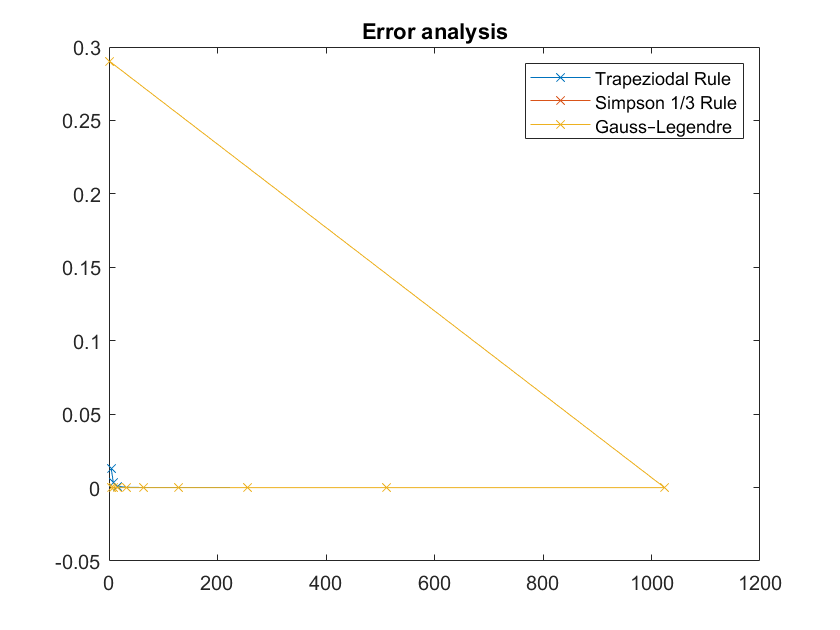


plot(N ,errorT,'-x')
hold on
plot(N,errorS,'-x')
plot(N,errorG,'-x')
hold off
legend("Trapeziodal Rule ","Simpson 1/3 Rule " ...
   ,"Gauss–Legendre ")
title("Error analysis")

Function Definition

function [x,w]=lgwt(N,a,b)

N=N-1;
N1=N+1; N2=N+2;
xu=linspace(-1,1,N1)';
% Initial guess
y=cos((2*(0:N)'+1)*pi/(2*N+2))+(0.27/N1)*sin(pi*xu*N/N2);
% Legendre-Gauss Vandermonde Matrix
L=zeros(N1,N2);
% Derivative of LGVM
Lp=zeros(N1,N2);
% Compute the zeros of the N+1 Legendre Polynomial
% using the recursion relation and the Newton-Raphson method
y0=2; 
% Iterate until new points are uniformly within epsilon of old points
while max(abs(y-y0))>eps
    
    
    L(:,1)=1;
    Lp(:,1)=0;
    
    L(:,2)=y;
    Lp(:,2)=1;
    
    for k=2:N1
        L(:,k+1)=( (2*k-1)*y.*L(:,k)-(k-1)*L(:,k-1) )/k;
    end
 
    Lp=(N2)*( L(:,N1)-y.*L(:,N2) )./(1-y.^2);   
    
    y0=y;
    y=y0-L(:,N2)./Lp;
    
end
% Linear map from[-1,1] to [a,b]
x=(a*(1-y)+b*(1+y))/2;      
%Compute the weights
w=(b-a)./((1-y.^2).*Lp.^2)*(N2/N1)^2;
end